# フーリエ変換

[⇦ メインメニューに戻る](matlab:open('../MainMenu.mlx'))

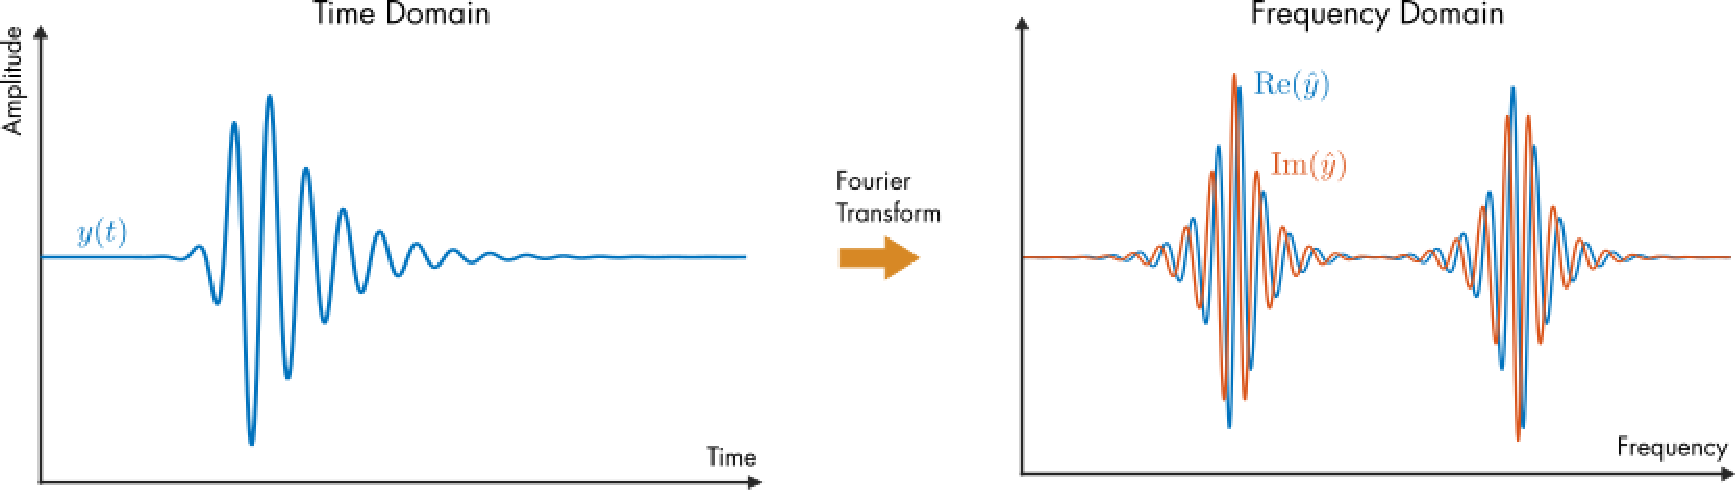

**始める前に：**

このライブスクリプトは、コードが表示され、出力がインラインで表示される状態で使用することを想定しています。MATLABツールストリップの**表示**タブの**表示**セクションで、**インラインで出力**を選択してください。または、ライブエディタウィンドウ右上のアイコン   を使って**インラインで出力**に設定することもできます。

 このライブスクリプトを操作することで、概念やコマンドの理解とともにMATLABに慣れることができます。さらに詳しい説明が必要な場合は、[MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted)（MATLABの基本を学べる無料の2時間オンラインチュートリアル）の受講を検討してください。

   最適な体験のために、指示や手順は示された順番で進めてください。前のセクションを完了してから新しいセクションに進みましょう。いくつかのセクションは前のセクションで作成された変数に依存しており、順番を守らないとエラーが発生します。

   と   のアイコンは、2種類のインタラクティブなアクティビティを示しています。   は、主にこのスクリプトで紹介された概念を、視覚的に理解するインタラクションを紹介します。 のインタラクションは、学習者が概念をどれだけ理解しているかを確認する目的で設計されており、教授による成績評価や完了チェックに使われる場合があります。

## はじめに

複素フーリエ級数を使って周期関数を解析することができます。複素フーリエ級数を思い出してください：


$$f(t) = \sum_{-\infty}^\infty c_n e^{ \frac{i n \pi}{L} t}$$


フーリエ係数 $c_n$ の大きさをプロットすることで、どの周波数が優勢かを特定できます。

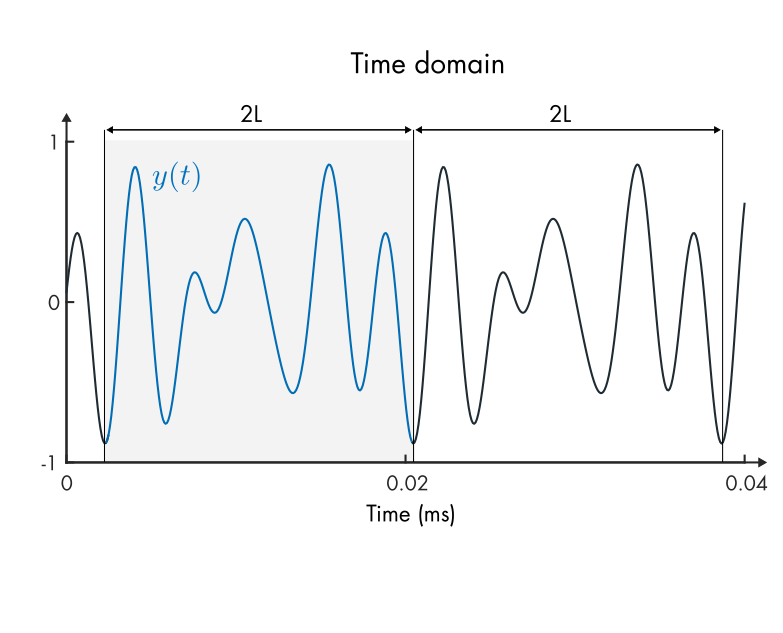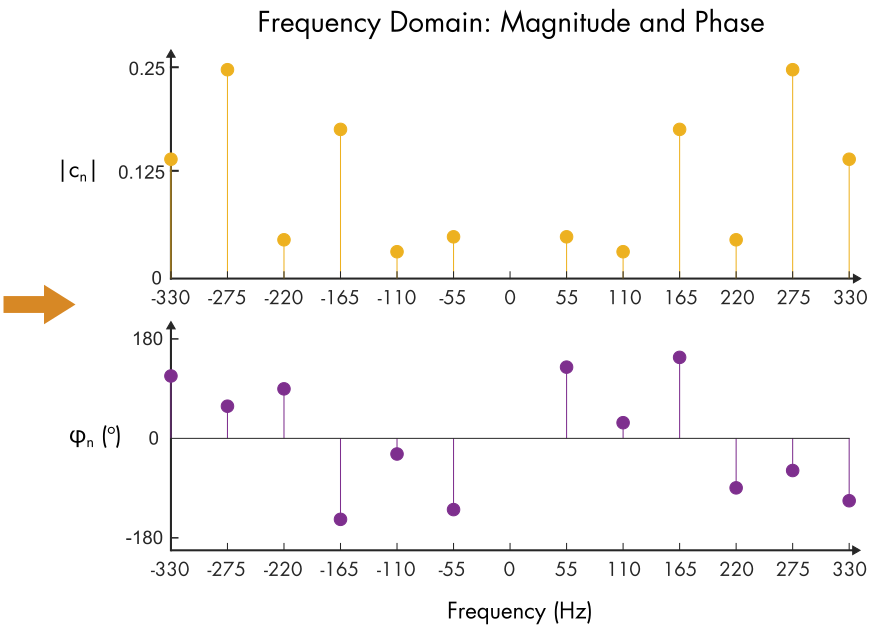

*時間領域と周波数領域における単純化したギターコード。最初のパネル：時間領域での2L周期関数。2番目のパネル：複素係数* $c_n$ *の大きさと位相。$y(t)$ *が実数であるため、係数は負の周波数で対称になります。*

このコードでは、C#（275 Hz）が優勢であることがわかります。

ギターが発する音声信号は主に周期的であるため、複素フーリエ級数は周波数領域の良い推定を提供します。しかし、非周期関数の周波数領域をどのように計算すればよいのでしょうか？

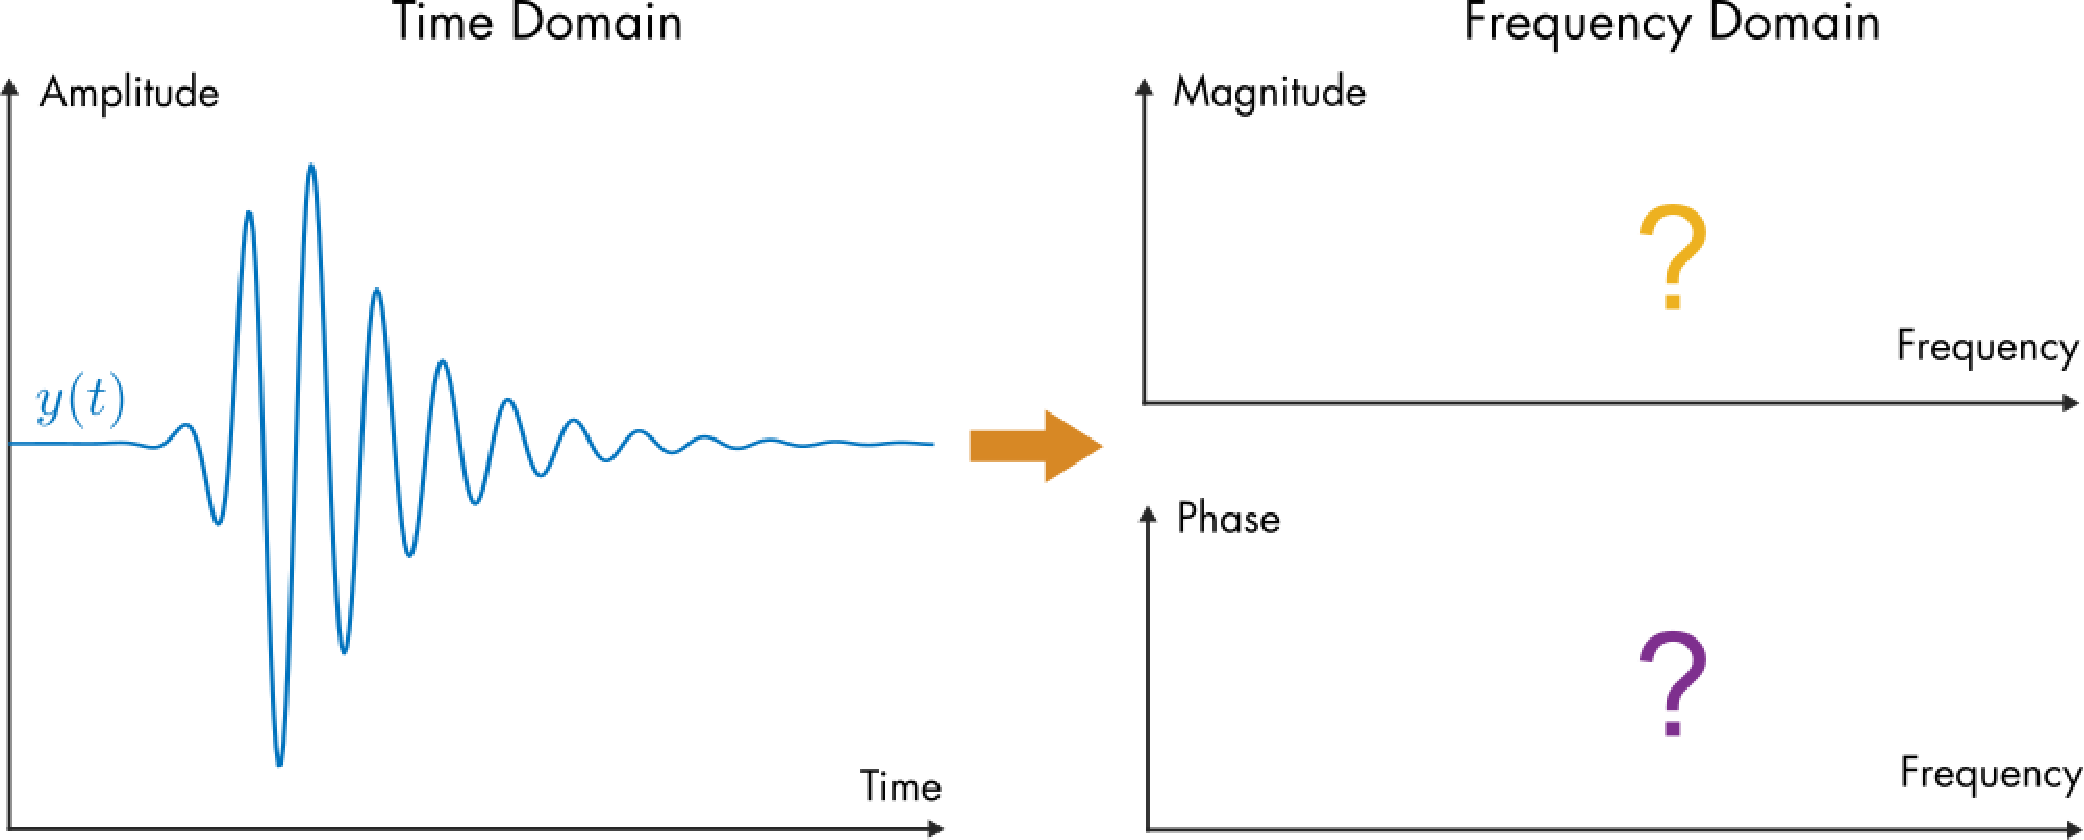

*$y(t)$ *の周波数領域プロットはどのようになるでしょうか？*

### **非周期関数をフーリエ級数で推定する**

非周期関数の大部分を含む有限区間（長さ $2L$）を仮定し、その区間でフーリエ級数係数を計算することが可能です。これにより関数の周波数成分に関する情報は得られますが、フーリエ級数は定義上周期的（周期 $2L$）であるため、元の関数を完全に表現することはできません。

   **アクティビティ。** 下のプロットは、非周期関数の複素フーリエ級数による推定を示しています。

- `L` を調整して、フーリエ級数を計算する区間の大きさを変更します。

- `N` を調整して、複素フーリエ級数で使用する周波数の数を変更します。

**タスク1.** **Show plot** を押してください。4つのプロットを観察しましょう。

- **Fourier Series Reconstruction** とラベルされたプロットは、フーリエ級数でモデル化された関数（最初のプロットで描かれている元の関数 $y(t)$ とは異なります）を示しています。

- 最初の周波数領域プロットは、複素級数係数 $|c_n|$ の大きさを示しています。

- y軸ラベルが $\angle c_n$ の2番目の周波数領域プロットは、位相角（ラジアン単位）を示しています。 

**タスク2.** `L = 1` および `N = 10` に設定してください。$y(t)$ は正確に再現されていますか？

**タスク3.** `L = 2`、次に `L = 3` に設定してください。推定は改善されますか？

**タスク4.** `L = 3` および `N = 10` のとき、ほとんどの周波数成分を捉えるのに十分なモード数ですか？もし不十分なら、モード数 `N` を増やして大部分の周波数成分が捉えられるか確認してください。

**タスク5.** 区間を `L = 5` に拡大してください。モード数 `N` を増やして大部分の周波数成分が捉えられるか確認してください。

L = 1; % The domain half-width
N = 10; % The number of Fourier modes to use in the series
 
fourierEstimateSech(L,N) % Helper function that creates the plots

 **考えてみましょう。**

- 周波数領域の分解能（つまり、スティック同士をより近づける）を上げたい場合、区間幅 `L` を増やすべきでしょうか、それとも周波数の数 `N` を増やすべきでしょうか？

- `L = 5` の場合、再構成のプロット $y_r$ には周期的なコピーが見られません。この場合、$y_r$ には周期的なコピーが存在するのでしょうか？

- 周期的なコピーが存在しないようにするには、区間はどれくらい大きくする必要がありますか？

- もはや周期的なコピーが存在しない場合、周波数領域の分解能はどのようになるでしょうか（つまり、スティック同士はどれくらい近くなるでしょうか）？

複素フーリエ級数は良い推定を与えることができますが、非周期関数を完全に捉えることは決してできません。これを可能にするには、フーリエ級数を計算する区間が無限大（$L \to \infty$）になる必要がありますが、これはフーリエ級数の定義とは両立しません。

一方、フーリエ変換は関数全体を周波数領域で解析的に表現することができます。

## 定義

関数 $f(t)$ のフーリエ変換は


$$\hat{f}(\omega) = \int_{-\infty}^\infty f(t) e^{-i\omega t} \ dt$$


この定義において、$\omega$ は角周波数です。元の信号 $f$ を $\hat{f}$ から得るには、逆フーリエ変換を使うことができます。逆変換は次のように定義されます。


$$f(t) = \frac{1}{2 \pi} \int_{-\infty}^\infty \hat{f}(\omega) e^{i\omega t} \ dt$$


フーリエ変換にはいくつかの異なる定義があります。この定義は、Symbolic Math Toolbox のフーリエ変換関数 [`fourier`](https://www.mathworks.com/help/symbolic/sym.fourier.html) および [`ifourier`](https://www.mathworks.com/help/symbolic/sym.ifourier.html) で使��れている定義と一致するため選ばれています。

## フーリエ変換の解析的評価

フーリエ変換は定義に従って手計算することも、表を利用することもできます。もう一つの方法は、Symbolic Math Toolbox の [`fourier`](https://www.mathworks.com/help/symbolic/sym.fourier.html) 関数を使うことです。下の例は、ガウス関数に対してこれら2つの方法を示しています。ガウス関数は、そのフーリエ変換もまたガウス関数になるという特徴があります。

 **例。** パラメータ $a$ を持つ単純なガウス関数は


$$y(t) = e^{- a t^2}$$


ガウス曲線は、明確に定義されており（比較的）計算しやすいフーリエ変換を持ちます。


$$\begin{array}{rl}
\hat{y}(\omega) &= \int_{-\infty}^\infty e^{-a t^2} e^{-i\omega t} \ dt
\\
&= \int_{-\infty}^\infty e^{- a( t^2 + i\omega t/a - \omega^2/(4a^2)) - \omega^2/(4a)} \ dt
\\
&= e^{ - \frac{\omega^2}{4 a}} \int_{-\infty}^\infty e^{- a (t+i\omega/(2a))^2} \ dt
\\
&= \sqrt{\frac{\pi}{a}} e^{ - \frac{ \omega^2}{4a}} 
\end{array}$$


Symbolic Toolbox の [`fourier`](https://www.mathworks.com/help/symbolic/sym.fourier.html) 関数を使って、フーリエ級数を計算し結果を検証することができます。

**タスク。** このセクションを実行してフーリエ変換を計算してください。

  **プロ・ヒント。** セクションを素早く実行するには、キーボードショートカット **Ctrl**+**Enter** を使いましょう。

syms t omega % Define the symbolic variables
syms a positive % a is a positive constant
y = exp(-a*t^2) % Define the function
yhat = fourier(y,t,omega) % Compute the Fourier transform

**タスク。** 関数 $y$ とそのフーリエ変換 $\hat{y}$ が下にプロットされています。このセクションを実行してプロットを表示してください。その後、下のスライダーを使ってパラメータ $a$ の値を調整し、プロットを再生成してください。

% Substitute a value for a
aValue = 2;
transformPlot(aValue) % Helper function that generates the plot

 **考えてみましょう。**

- $a$ を大きくすると $y(t)$ はどのように変化しますか？

- $a$ を大きくすると $\hat{y}(t)$ はどのように変化しますか？

- このプロットから、時間領域の関数とその周波数成分の間にはどのような一般的な関係があるように見えますか？

## **実信号の解析的近似**

ギターの音声信号は実際には周期的ではありません。実際には、急速に増幅し、その後指数関数的に減衰します。

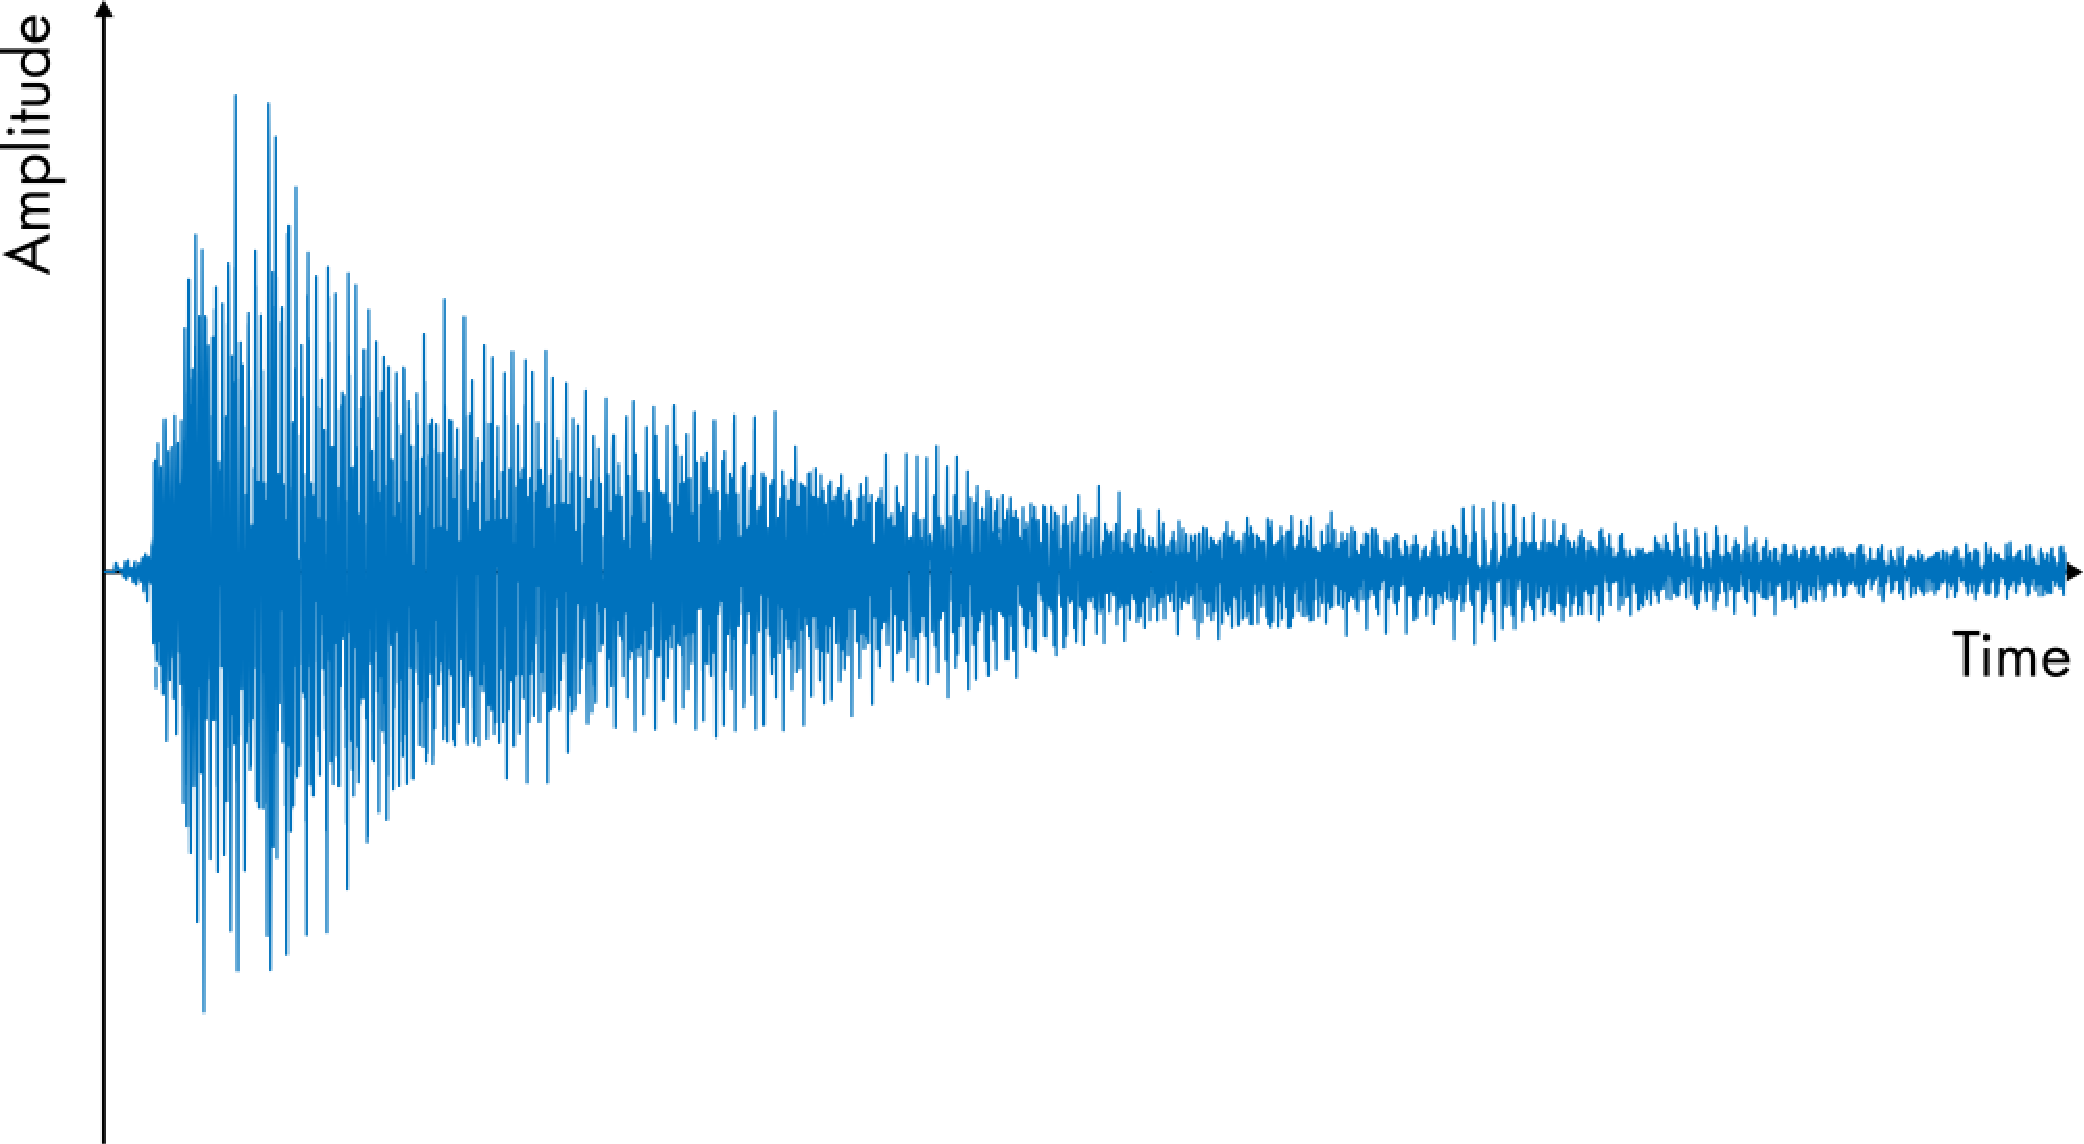

*時間領域におけるギターの「A」音の信号*

前のスクリプトでは、信号の小さなウィンドウをフーリエ級数で解析しました。非周期的な信号全体を解析するには、フーリエ変換を適用するのが有効です。ギターの音声信号には多くの高調波が含まれ、立ち上がり時間もありますが、単一周波数と減衰する指数関数の積で十分に近似できます：


$$y(t) = e^{-at} \sin ( 2 \pi \omega_0 t )$$


ここで $a$ は減衰率、$\omega_0$ は基本周波数です。ギターのA音の場合、$\omega_0$ の妥当な値は $2 \pi \cdot 110$（110 Hzに相当）です。この関数は、高調波のために追加のサイン項を加えることで、実際の音声信号をよりよく表現するように簡単に修正できます。

   **アクティビティ。** このアクティビティでは、信号 $y(t)$ を構成し、プロットし、その周波数成分を解析します。

**タスク1.** あらかじめ定義された `a`, `omega0`, `t` の値を使って、$y(t)$ をベクトル `y` として計算し、プロットできるようにしてください。

**ヒント。** `t` はベクトルなので、要素ごとの積（**.***）を使いましょう。

omega0 = 2*pi*110; % angular frequency corresponding to 110 Hz
a = 1.5; % Decay rate (per second)
t = 0:1/44.1e3:3; % Time variable
% Compute y here



正しければ、`y` には次のような値のベクトルが含まれているはずです：

**タスク2.** [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html) を使って、信号 `y` を `t` に��してプロットしてください。軸ラベルは [`xlabel`](https://www.mathworks.com/help/matlab/ref/xlabel.html) および [`ylabel`](https://www.mathworks.com/help/matlab/ref/ylabel.html) を使って付けましょう。

figure % Creates a new figure
% Plot y against t here



関数 $y(t)$ はフーリエ変換による解析に適した形ではありません。指数関数項 $e^{-t}$ は負の時間で指数的に増大し、積分が収束しなくなります。また、実際の音声信号は「負の時間」で増大することはないため、これは現実的でもありません。関数を指定した時刻 $t_c$ で打ち切るには、ヘヴィサイドステップ関数 $H(t)$ を使うことができます：


$$y_c(t) =  H(t-t_c) e^{-a(t-t_c)} \sin ( 2 \pi \omega_0 t )$$


次のことを思い出してください


$$H(t) = \left\{ \begin{array}{rl} 0 \ \ & t < 0 \\ 1 \ \ & t \geq 0 \end{array} \right.$$


**タスク3.** あらかじめ定義された `a`, `omega0`, `tc`, `t` の値を使って、`yc` をベクトルとして計算し、プロットできるようにしてください。ヘヴィサイドステップ関数には組み込み関数 [`heaviside`](https://www.mathworks.com/help/symbolic/heaviside.html) を使うことができます。

tc = 0.5; % Cutoff time
% Compute yc here
yc = heaviside(t-tc).*exp(-a.*(t-tc)).*sin(omega0.*t); 


**タスク4.** `yc` を `t` に対してプロットし、時間領域での信号を確認してください。この信号は周波数領域でどのように見えると予想されますか？

% Create your plot here



正しければ、プロットは次のように表示されるはずです

plot(t,yc)
xlabel("t (s)")
ylabel("Amplitude")

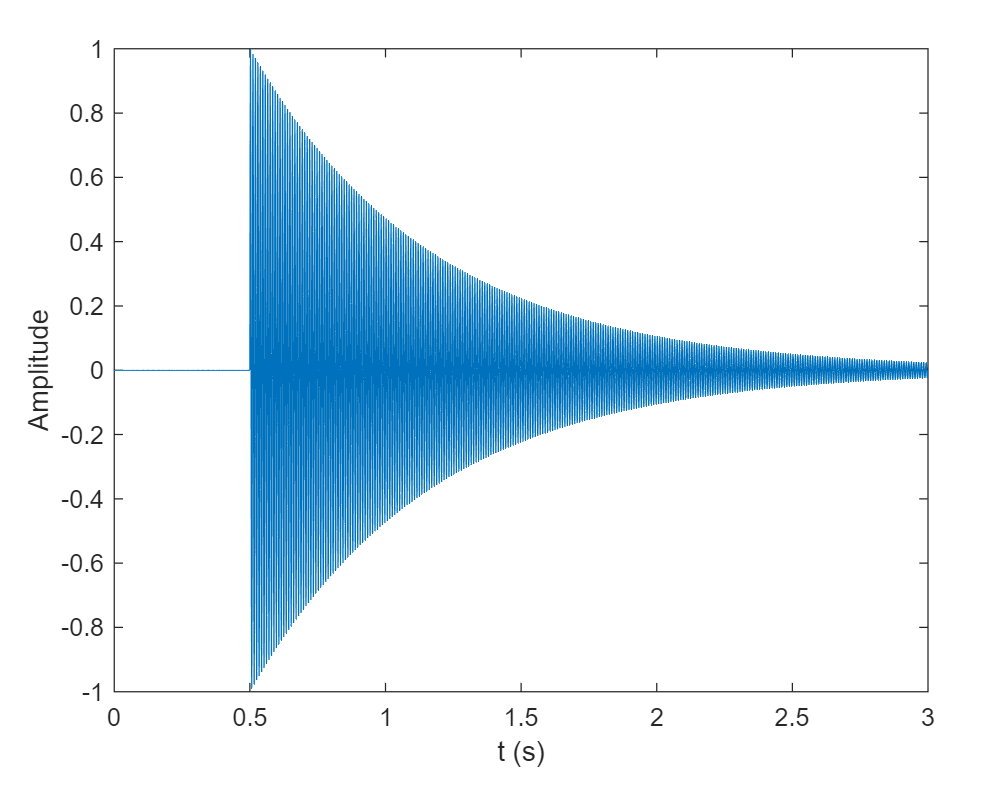

**タスク5.** このセクションを実行して `yc` をサウンドとして再生してください。

Fs = 1/(t(2)-t(1)); % The sample rate
soundsc(yc,Fs) % Play the sound

**タスク6.** $y_c$ のフーリエ変換には解析的な式があります。積分のスキルを試してみましょう：定義式を使って $y_c(t)$ のフーリエ変換を手計算で求めてください。


$$\hat{y_c}(\omega) = \int_{-\infty}^\infty y_c(t) e^{-i\omega t} \ dt$$


**ヒント**：サイン関数を複素指数関数で書き換え、ヘヴィサイドステップ関数に基づいて区間を分割しましょう。

あるいは、Symbolic Math Toolbox を使ってフーリエ変換を計算することもできます。

**タスク7.** `yc` をシンボリックな式として定義してください。まず、$t$ の[シンボリック変数を定義](https://www.mathworks.com/help/symbolic/create-symbolic-numbers-variables-and-expressions.html)します。

次に、`t` を使って $y_c$ を表現してください。式の中では、あらかじめ定義された定数 `a`, `omega0`, `tc` を使うことができます。この式は **タスク3** で使ったものと同じである必要があります。違いは、入力の `t` がベクトルではなくシンボリック変数である点です。

% Write your code here
syms t
yc = heaviside(t-tc).*exp(-a.*(t-tc)).*sin(omega0.*t)

**タスク8.** `yc` のフーリエ変換を計算するには、Symbolic Math Toolbox の [`fourier`](https://www.mathworks.com/help/symbolic/sym.fourier.html) 関数を使ってください。結果は `yhat` として定義します。

% Compute the Fourier transform here
yhat = fourier(yc)

**タスク9.** $|\hat{y}|$ の大きさを $\omega$ の区間 `[0,1250]` でプロットしてください。シンボリック式のプロットには [`fplot`](https://www.mathworks.com/help/matlab/ref/fplot.html) を次の構文で使います。

ここで `f` はプロットするシンボリック式、`xinterval` は区間の範囲です。プロット作成後、縦軸の範囲を [`ylim`](https://www.mathworks.com/help/matlab/ref/ylim.html) で `[0,0.25]` に設定してください。軸ラベルも付けましょう。

% Create your plot of yhat here
fplot(abs(yhat),[0 1250])
ylim([0 0.25])
ylabel("$|\hat{y}|$","Interpreter","latex")
xlabel("$\omega$ (rad/s)","Interpreter","latex")

 **考えてみましょう。**

- 大きさ $| \hat{y} |$ をプロットすると、110 Hz（$\approx$691 rad/s）でピークが見られます。この関数のどの要素がこのピークを生み出していますか？

- 純粋な110 Hzのサイン波のフーリエ係数の大きさのプロットはどのようになるでしょうか？

- このプロットは純粋なサイン波のフーリエ係数のプロットとどのように似ていて、どのように異なりますか？

- ヘヴィサイド関数と指数減衰関数は周波数領域にどのような影響を与えますか？

## キャリア波変調

前のアクティビティで解析した信号は、2つの異なる成分、すなわち時間とともにゆっくり変化する*エンベロープ*と、基礎となる「高」周波数（110 Hz）の波から成ると考えることができます。

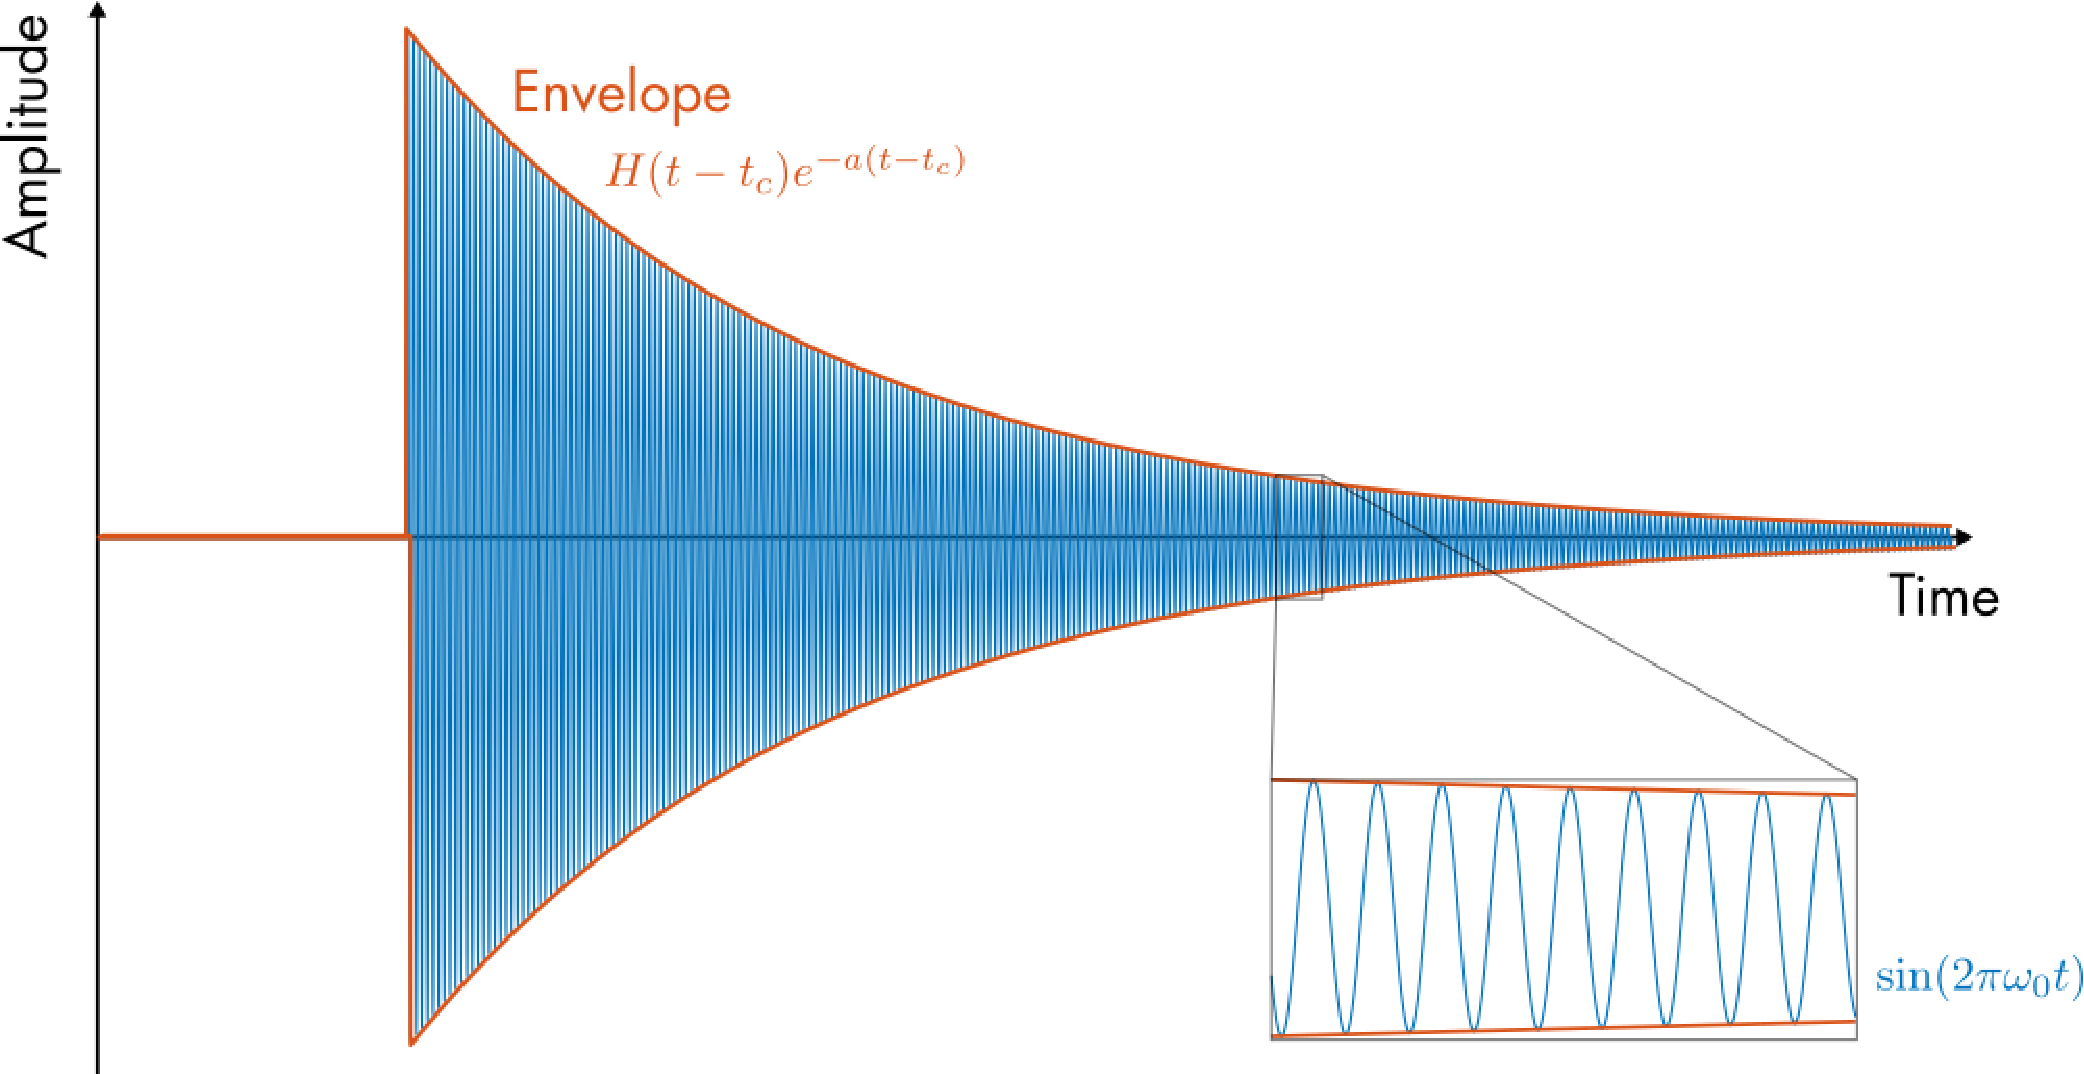

*時間領域で生成された音声信号の2つの基本成分のイラスト。*

このような混合信号は、信号伝送の応用でよく見られます。高周波のキャリア波が信号に基本周波数を与えます。キャリアは低い周波数で変調され、情報が符号化されます。例えば、AMラジオでは振幅変調が使われています。ラジオ信号の基本周波数が（振幅で）変調され、送信される音声信号に合わせられます。AMラジオのキャリア周波数は540～1600 kHzです。ラジオを局に合わせるとき、キャリア周波数に合わせています。その後、受信機は遅い変調から音声情報を取り出します。

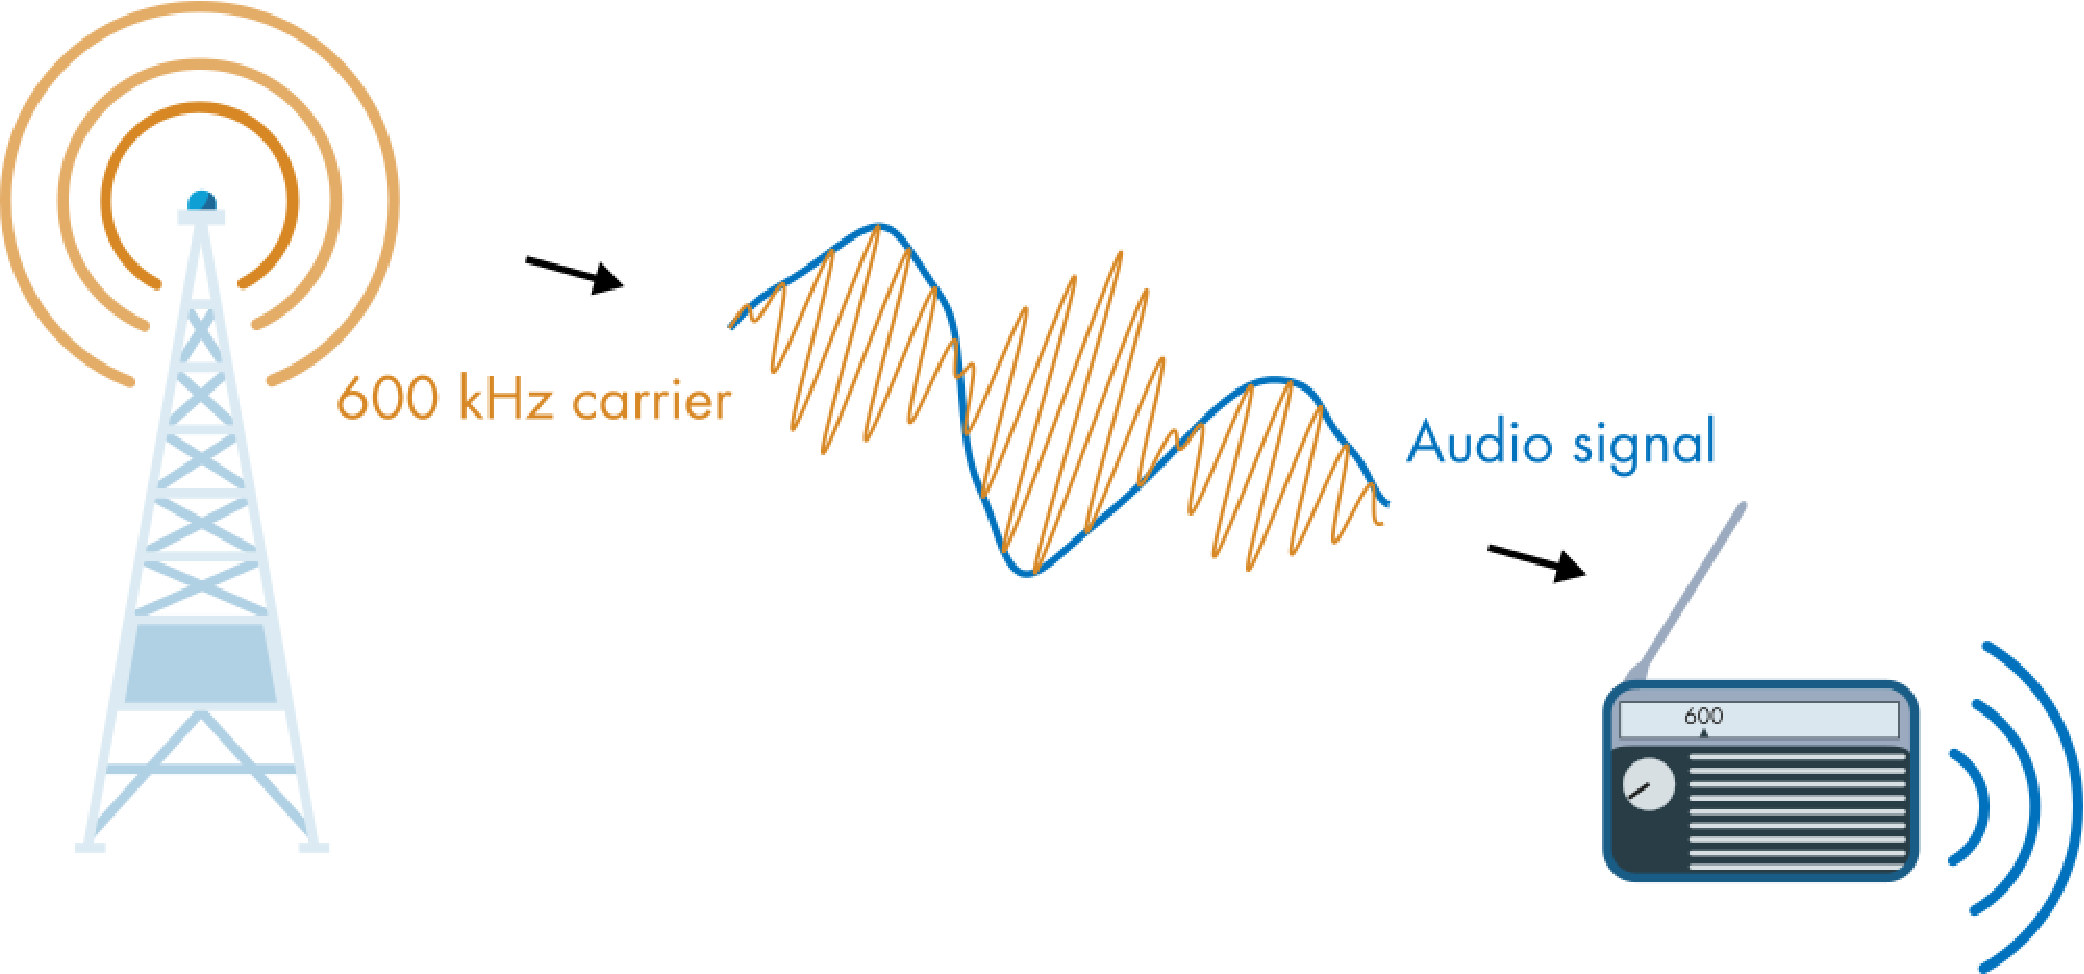

*AMラジオを600 kHzに合わせると、600 kHzキャリアの振幅変調を受信し、それを使ってスピーカーを駆動します。*

干渉を防ぐため、変調は最大5 kHzまでに制限されています。この周波数では音声信号を完全に再現することはできません。これがAMラジオの音質がFMラジオより劣る理由の一つです。

### 周波数領域

上の図に示した変調AM信号の特徴を考えてみましょう。この信号は周波数領域でどのように見えると予想されますか？キャリア周波数を変えると周波数成分はどのように変化するでしょうか？このセクションでは、フーリエ変換を使って変調信号を解析します。

連続フーリエ変換を適用する際は、明確に定義された（解析的な）フーリエ変換を持つ関数を扱う必要があります。そのような関数はいくつかありますが、最も扱いやすいものの一つがガウス変調サイン関数です：


$$g(t) = A \sin( \omega_0 t ) e^{- \frac{(t-t_0)^2}{2 c^2 } }$$


この関数は特定の実信号を表すものではありませんが、シンプルで、キャリアや変調の変化が信号の周波数成分にどのような影響を与えるかを直感的に理解するのに役立ちます。

   **アクティビティ。** 下のプロットは、時間領域でのガウス変調サイン関数を示しています。セクションを実行してプロットを表示してください。その後、各パラメータを調整し、波形の変化に注目しましょう。

A = 1.5; % Amplitude
f0 = 15; % Carrier frequency (Hz)
c = 0.1; % Gaussian "width"
t0 = 0.5; % Center position (s)
omega0 = f0*2*pi; % Angular frequency (rad/s)
sineGaussPlot(A,omega0,t0,c)

 **考えてみましょう。**

- この関数は周波数領域でどのように見えると思いますか？（つまり、$\hat{f}$ のプロットはどのようになるでしょうか？）

- 各パラメータ（$A$, $\omega_0$, $c$, $t_0$）を増やすと、周波数領域のプロットはどのように変化すると予想されますか？

 **演習。** この演習では、$g(t)$ のフーリエ変換を計算します。

**タスク1.**（オプション）$g(t)$ の簡略版のフーリエ変換を手計算で求めてみましょう：


$$g(t) = \sin(  t ) e^{- \frac{t^2}{2  } }$$


**ヒント**：サイン関数を複素指数関数で書き換え、項を展開して平方完成しましょう。

**タスク2.** Symbolic Math Toolbox を使って元の関数を定義してください：


$$g(t) = A \sin( \omega_0 t ) e^{- \frac{(t-t_0)^2}{2 c^2 } }$$


`g` の式には、あらかじめ定義されたシンボリック変数を使ってください。

% Predefined symbolic variables
syms t omega real
syms omega_0 t_0 c A positive
% Write an expression for g here
g = A*sin(omega_0*t)*exp(-(t-t_0)^2/(2*c^2))

**タスク3**. [`fourier`](https://www.mathworks.com/help/symbolic/sym.fourier.html) を使って `g` のフーリエ変換を計算し、結果を `ghat` に保存してください。

% Compute the Fourier transform here
ghat = fourier(g,omega)

**タスク4.** [`simplify`](https://www.mathworks.com/help/symbolic/simplify.html) 関数を使って `ghat` を簡単化してください。

% Simplify ghat here
ghat = simplify(ghat)

**実部と虚部**

$\hat{g}$ の関数形は少し複雑です。パラメータの変化が周波数成分にどのような影響を与えるか直感的に理解するために、結果をプロットするのが有効です。

   **アクティビティ。** このアクティビティでは、$g$ の変化が周波数領域にどのような影響を与えるか、$\hat{g}$ の実部と虚部をプロットして確認します。

**タスク1.** **Show plots** をクリックしてください。

% This plots the Gaussian-modulated sinusoid and its Fourier transform
A = 1.5; % Amplitude
f0 = 15; % Carrier frequency (Hz)
c = 0.1; % Gaussian "width"
t0 = 0.5; % Center position (s)
omega0 = f0*2*pi; % Angular frequency (rad/s)
 

% Compute ghat 
omega = linspace(-250,250,5e3);
ghat = -A*sqrt(pi/2)*1i*c.*(exp(-0.5*(omega-omega0).*(c^2*omega-c^2*omega0+2*t0*1i)) - ...
                            exp(-0.5*(omega+omega0).*(c^2*omega+c^2*omega0+2*t0*1i)));
sineGaussComplexPlot(omega,ghat,A,omega0,t0,c) % Helper function that generates the plot

**タスク2.** 各パラメータを独立に増やしてみましょう。それぞれを増やすと周波数領域のプロットはどのように変化しますか？

**タスク3.** 周波数領域で負の周波数と正の周波数に非常によく似た2つのコピーが現れることに気づくはずです。$t_0$ を比較的小さい値に設定して、違いをより明確にしてみましょう。これらのコピーはどのような関係にあるように見えますか？

 **考えてみましょう。**

- キャリア周波数を変えると周波数領域のプロットはどのように変化しますか？

- ガウス幅を広げると周波数領域はどうなりますか？これは理にかなっていますか？

- なぜ負の周波数成分が現れるのでしょうか？それには現実的な意味がありますか？

**大きさと位相**

フーリエ変換 $\hat{f}$ の実部と虚部をプロットすることは、基礎となる関数成分を理解するのに役立ちます。複素フーリエ級数と同様に、実関数を再構成するには負の周波数成分が必要です。これは、複素指数関数を使うことで虚数成分が生じ、それを「打ち消して」実関数を作る必要があるためです。しかし、周波数領域を理解するには、通常は大きさと位相のプロットの方が有用です。

   **アクティビティ。** このアクティビティでは、$g$ の変化が周波数領域にどのような影響を与えるか、$\hat{g}$ の大きさと位相をプロットして確認します。

**タスク1.** **Show plots** をクリックしてください。

% This plots the Gaussian-modulated sinusoid and it's Fourier transform
A = 1.5; % Amplitude
f0 = 15; % Carrier frequency (Hz)
c = 0.1; % Gaussian "width"
t0 = 0.5; % Center position (s)
omega0 = f0*2*pi; % Angular frequency (rad/s)
 

sineGaussMagPhasePlot(A,omega0,t0,c) % Helper function that generates the plot

**タスク2.** 各パラメータを独立に増やしてみましょう。それぞれを増やすと周波数領域のプロットはどのように変化しますか？

 **考えてみましょう。**

- 位相プロット $\angle g$ を見直しましょう。位相は angle 関数で推定され、常に $-\pi$ から $\pi$ の間の角度が返されます。解析的な関数の位相は本当に $-\pi$ から $\pi$ の間にあるのでしょうか？複素数 $Ae^{i \phi}$ の位相は $\phi$ であることを思い出してください。

- どのパラメータが周波数領域の大きさプロットに影響しますか？何が変化しますか？

- どのパラメータが位相プロットに影響しますか？何が変化しますか？

[⇦ メインメニューに戻る](matlab:open('../MainMenu.mlx'))

function fourierEstimateSech(L,Nmodes)
    % This function creates a figure that illustrates
    % how the Fourier series only models a finite domain

    % Parameters
    tf = 12;
    ts = 2;
    tmid = 6;
    sigma = 0.2;
    freq = 1.6;
    Nt = 1000;
    
    % Domain and function
    ylims = [-1,1];
    tlims = [0,tf];
    freqLims = [-4,4];
    t = linspace(tlims(1),tlims(2),Nt);
    sechValue = 2./(exp((0.2*t-ts)/sigma) + exp(-(t-ts)/sigma));
    y = sin(2*pi*freq*t).*sechValue/1200;

    % Extract the correct interval
    dLims = round( (tmid + [-L,L])*Nt/tf );
    dIdx = dLims(1):dLims(end);
    yc = y(dIdx);
    tc = t(dIdx);

    % Estimate coefficients using trapezoid rule
    nvec = -Nmodes:1:Nmodes;
    freq = nvec/(2*L);
    c = zeros(1,numel(nvec));
    for k = nvec + Nmodes + 1
        c(k) = 1/(2*L)*trapz(tc,exp(-1i*nvec(k)*pi/L*tc).*yc);
    end

    % Compute the Fourier series estimate
    ft = zeros(size(t));
    for k = 1:numel(nvec)
        ft = ft + c(k)*exp(1i*pi/L*nvec(k).*t);
    end

    % Create the figure and subplots
    colors = lines(4);
    figure("OuterPosition",[1,1,800,400])
    subplot(2,2,1)
    plot(t,y,"Linewidth",1)
    patch([tc(1),   tc(1),   tc(end), tc(end),  tc(1)],...
          [ylims(1),ylims(2),ylims(2),ylims(1), ylims(1)],[0.3,0.3,0.3],"FaceAlpha",0.1,EdgeAlpha=0.75)
    ylim(ylims)
    xlim(tlims)
    ylabel("$y(t)$ (original)","Interpreter","latex")
    title("Time Domain","Interpreter","latex")

    subplot(2,2,3)
    plot(t,real(ft),"Linewidth",1)
    patch([tc(1),   tc(1),   tc(end), tc(end),  tc(1)],...
          [ylims(1),ylims(2),ylims(2),ylims(1), ylims(1)],[0.3,0.3,0.3],"FaceAlpha",0.1,EdgeAlpha=0.75)
    xlim(tlims)
    ylim(ylims)
    xlabel("Time (s)","Interpreter","latex")
    ylabel("$y_r(t)$ (reconstructed)","Interpreter","latex")
    title("Fourier Series Reconstruction","Interpreter","latex")

    subplot(2,2,2)
    stem(freq,abs(c),"Filled","Color",colors(3,:))
    xlim(freqLims)
    ylabel("$| c_n |$","Interpreter","latex")
    title("Frequency Domain","Interpreter","latex")

    subplot(2,2,4)
    stem(freq,angle(c),"Filled","Color",colors(4,:))
    xlim(freqLims)
    xlabel("Frequency (Hz)","Interpreter","latex")
    ylabel("$\angle c_n$","Interpreter","latex")

end


function transformPlot(a)
    % Plots the transform of the defined function

    t = linspace(-10,10,500);
    y = exp(-a*t.^2); % Define the function
    omega = linspace(-10,10,500);
    yhat = sqrt(pi/a)*exp((-omega.^2/(4*a)));

    % Create the plots
    figure("Position",[1 1 800 300])
    
    subplot(1,2,1)
    plot(t,y,"LineWidth",1)
    ylim([0,2])
    xlabel("$t$","Interpreter","latex")
    ylabel("$y(t)$","Interpreter","latex")

    subplot(1,2,2)
    plot(omega,yhat,"LineWidth",1)
    ylim([0,2])
    xlabel("$\omega$","Interpreter","latex")
    ylabel("$\hat{y}(t)$","Interpreter","latex")

end

function sineGaussPlot(A,omega0,t0,c)
    % Plots a Gaussian modulated sinusoidal function
    % with the Gaussian modulation displayed separately
    
    t = linspace(0,1,1e3);
    g = A*sin(omega0*t).*exp(-(t-t0).^2/(2*c^2));
    modulation = A*exp(-(t-t0).^2/(2*c^2));

    figure
    plot(t,g,t,modulation,"LineWidth",1)
    ylim([-3,3])
    xlabel("$t$","Interpreter","latex")
    ylabel("$g$","Interpreter","latex")
    title("Time Domain","Interpreter","latex")
end

function sineGaussComplexPlot(omega,ghat,A,omega0,t0,c)
    % Creates a plot of the Gaussian modulated sinusoid

    % Compute g
    t = linspace(0,1,5e3);
    g = A*sin(omega0*t).*exp(-(t-t0).^2/(2*c^2));

    % Plots a Gaussian modulated sinusoid
    % in time and frequency domains (real/imaginary part)
    figure("Position",[1 1 800 400])
    subplot(1,2,1)
    plot(t,g,"LineWidth",1)
    ylim([-3,3])
    xlabel("$t$","Interpreter","latex")
    ylabel("$g$","Interpreter","latex")
    title("Time Domain","Interpreter","latex")
    
    subplot(1,2,2)
    hold on
    plot(omega,real(ghat),"LineWidth",0.75)
    plot(omega,imag(ghat),"LineWidth",0.75)
    ylim([-0.5,0.5])
    xlim([omega(1),omega(end)])
    xlabel("$\omega$ (rad/s)","Interpreter","latex")
    ylabel("$\hat{g}$","Interpreter","latex")
    legend("Re$(\hat{g})$","Im$(\hat{g})$","Interpreter","latex");
    title("Frequency Domain","Interpreter","latex")
end

function sineGaussMagPhasePlot(A,omega0,t0,c)
    % Creates a plot of the Gaussian modulated sinusoid
    % and its Fourier transform
    
    % Compute g
    t = linspace(0,1,5e3);
    g = A*sin(omega0*t).*exp(-(t-t0).^2/(2*c^2));

    % Compute ghat 
    omega = linspace(-250,250,5e3);
    ghat = -A*sqrt(pi/2)*1i*c.*(exp(-0.5*(omega-omega0).*(c^2*omega-c^2*omega0+2*t0*1i)) - ...
                                exp(-0.5*(omega+omega0).*(c^2*omega+c^2*omega0+2*t0*1i)));

    % Plots a Gaussian modulated sinusoid
    % in time and frequency domains (mag/phase part)
    figure("Position",[1 1 800 600])
    
    subplot(2,2,[1,3])
    plot(t,g,"LineWidth",1)
    ylim([-3,3])
    xlabel("$t$","Interpreter","latex")
    ylabel("$g$","Interpreter","latex")
    title("Time Domain","Interpreter","latex")
    
    colors = lines(4);
    subplot(2,2,2)
    hold on
    plot(omega,abs(ghat),"Color",colors(3,:),"LineWidth",1)
    ylim([-0.5,0.5])
    xlim([omega(1),omega(end)])
    ylabel("$|\hat{g}|$","Interpreter","latex")
    title("Frequency Domain","Interpreter","latex")

    subplot(2,2,4)
    hold on
    plot(omega,angle(ghat),"Color",colors(4,:),"LineWidth",1)
    ylim([-4,4])
    xlim([omega(1),omega(end)])
    xlabel("$\omega$ (rad/s)","Interpreter","latex")
    ylabel("$\angle \hat{g}$ (rad)","Interpreter","latex")
end

% Suppressed warnings
%#ok<*NASGU> 